# **Programa de comunicacion BPSK con filtro formador y filtro acoplado con 1 muestra por simbolo**

Esta rutina genera la simulation de un sistema de comunicaciones BPSK utilizando filtro formador, un filtro acoplado y un SNR predefinida.

clear all; close all;

## TRANSMISOR

Se genera una serial BPSK con los datos aleatorios. Y los parametros indicados

num_bits : especifica el numero de bits a transmitir, debe ser numero par y mayor a 100

srate: 

filt    : especifica si se utiliza un filtro     

'cosa' para coseno alzado, 

'sqrt' para raiz de coseno alzado

'rect'    para un filtro rectangular            

muest_porbit : especifica el numero de muestras por bit que se utilizaran en la simulacion, debe ser numero impar

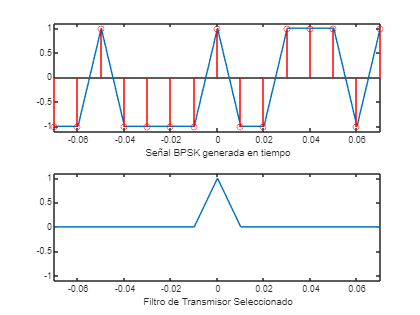

num_bits = 100;       %Numero de bits a transmitir 
srate=.01;              %Intervalo de muestreo equivalente a fs
filt='rect';            %Tipo de filtro transmisor, tambien puede ser cosa y rect 
muest_porbit=1;         %Numero de muestras por simbolo? o bit?
%   Generacion de BPSK
[filtrotrans,senalBPSK,t,senaldig]=BPSK_pb(num_bits,srate,filt,muest_porbit);

## RECEPECCION CON RUIDO 

La señal es pasada a travez de un filtro acoplado al filtro de transmisor para maximizar Ia relacion senal a ruido.

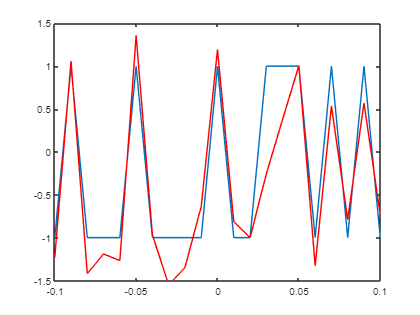

SNR_deseado_dB = 5; 
senal_masruido = awgn(SNR_deseado_dB,senalBPSK,t);

## RECEPTOR CON FILTRO ACOPLADO

La señal es pasada a travez de un filtro acoplado al filtro de transmisor para maximizar Ia relaciOn sepal a ruido.

Awgn toma una señal trans y le suma una componente de ruido aditivo gausiano con varianza especificada tal que cumple con la SNR deseada en dB; se considera que el filtro de transmisor estan normalizados con energia unitaria solo se necesita variar la potencia del ruido para especificar una cierta relacion señal a ruido.

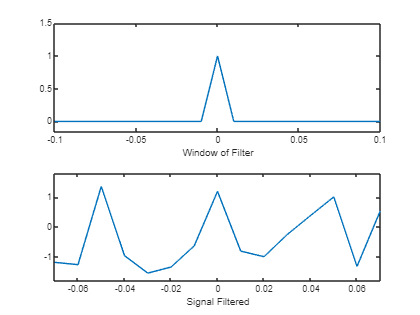

senal_recib=matched_filter(filtrotrans,senal_masruido,t);

## DISPOSITIVO DE DECISION

La señal recibida es pasada por el circuito de decision que regresa el vector de bits detectados, asi como el numero de bits erroneos contados.Decide en base al umbral, el valor del bit recibido y a señal detectada.

Necesita el nUmero de bits y el numero de muestras por bit para sincronizarse a partir de cero.

Regresa tambien el numero de bits erroneos 

num_bits_erroneos = 1

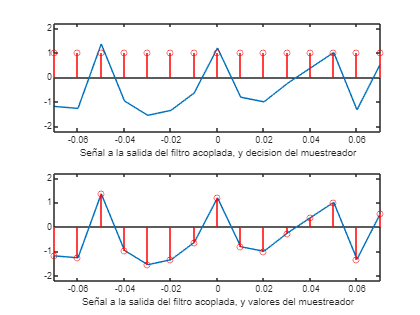

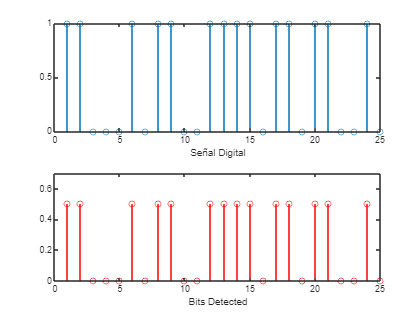

umbral=0; 
[num_bits_erroneos,bits_detectadosj]=decision(umbral,senal_recib,num_bits,muest_porbit,t,senaldig,srate);

## GRAFICACION BER TEORICO Y SIMULADO

Los bits con error se grafican sobre la curva teórica. La señal recibida es pasada por el circuito de decisión que regresa el vector de bits detectados, así como el número de bits erróneos contados.Se grafica la curva de BER contra relacion serial a ruido teorica, asi como el punto de la simulacion obtenida.

pber_sim = 0.0100

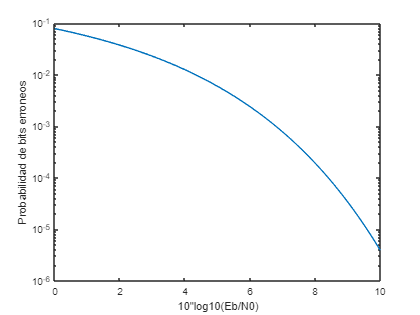

grafica_BERySNR(SNR_deseado_dB, num_bits_erroneos, num_bits);